%% Configuración inicial
clear all; close all; clc;

% Parámetros del solenoide
nL = 5;         % Número de espiras: vueltas del alambre conductor que generan campo magnético
N = 30;         % Puntos por espira: discretización para aproximar la espira mediante elementos diferenciales
R = 1.0;        % Radio de las espiras (m): define el tamaño de cada vuelta del solenoide
sz = 0.5;       % Separación entre espiras (m): altura entre espiras, genera un solenoide helicoidal
I = 300;        % Corriente (A): fuente del campo magnético según la ley de Biot-Savart
mu0 = 4*pi*1e-7; % Permeabilidad magnética del vacío: constante fundamental del magnetismo
km = mu0 * I / (4*pi); % Constante de Biot-Savart: factor que aparece en la fórmula para B

%% Creación del grid espacial
% Definimos el volumen donde calcularemos el campo
x = linspace(-3, 3, 30); % Eje X: define el dominio en la dirección horizontal
y = linspace(-3, 3, 30); % Eje Y: incluye varias posiciones para representar el espacio en torno al solenoide
z = linspace(-2, nL*sz+2, 40); % Eje Z: incluye el solenoide y márgenes superior e inferior

% Creamos el grid 3D
[X, Y, Z] = meshgrid(x, y, z); % Malla tridimensional de puntos donde se calculará el campo magnético

% Inicialización de matrices para componentes del campo
Bx = zeros(size(X)); % Componente X del campo magnético
By = zeros(size(Y)); % Componente Y del campo magnético
Bz = zeros(size(Z)); % Componente Z del campo magnético

%% Creación de las espiras
theta = linspace(0, 2*pi, N+1); % Ángulos que recorren una vuelta completa
theta = theta(1:end-1); % Eliminamos el último punto para evitar duplicación (0 = 2π)
dtheta = theta(2) - theta(1); % Incremento angular para cada segmento

% Pre-alocación para coordenadas de las espiras
espira_x = zeros(nL, N); % Coordenada X de cada punto de las espiras
espira_y = zeros(nL, N); % Coordenada Y de cada punto de las espiras
espira_z = zeros(nL, N); % Coordenada Z para cada espira (a distintas alturas)
dl_x = zeros(nL, N);     % Componente X del vector dl (elemento de corriente)
dl_y = zeros(nL, N);     % Componente Y del vector dl

for k = 1:nL
    % Posiciones de los puntos en la espira k
    espira_x(k,:) = R * cos(theta); % Coordenadas X de los puntos en la espira
    espira_y(k,:) = R * sin(theta); % Coordenadas Y de los puntos en la espira
    espira_z(k,:) = (k-1)*sz * ones(1,N); % Coordenada Z fija para cada espira
    
    % Diferenciales de línea (dl)
    dl_x(k,:) = -R * sin(theta) * dtheta; % Componente X del vector tangente dl (ley de Biot-Savart)
    dl_y(k,:) = R * cos(theta) * dtheta;  % Componente Y del vector tangente dl
    % El vector dl representa el sentido y magnitud del elemento de corriente en la espira
end

%% Cálculo del campo magnético (Ley de Biot-Savart)
fprintf('Calculando campo magnético...\n');

Calculando campo magnético...


tic; % Iniciar cronómetro

% Vectorizamos los puntos de las espiras
all_espira_x = espira_x(:); % Coordenadas X de todos los elementos de corriente
all_espira_y = espira_y(:); % Coordenadas Y de todos los elementos
all_espira_z = espira_z(:); % Coordenadas Z
all_dl_x = dl_x(:);         % Componentes X de dl
all_dl_y = dl_y(:);         % Componentes Y de dl

% Tamaño del grid
[ny, nx, nz] = size(X);

% Calculamos el campo para cada punto del grid
for i = 1:ny
    for j = 1:nx
        for k = 1:nz
            % Vector desde el elemento de corriente al punto de observación
            rx = X(i,j,k) - all_espira_x;
            ry = Y(i,j,k) - all_espira_y;
            rz = Z(i,j,k) - all_espira_z;
            
            % Distancia al cubo (norma^3), necesaria en Biot-Savart
            r3 = (rx.^2 + ry.^2 + rz.^2).^(3/2);
            r3(r3 < (0.1*R)^3) = Inf; % Evitar división por cero cerca del alambre
            
            % Producto cruz dl × r (solo dl_x y dl_y, ya que dl_z = 0)
            cross_x = all_dl_y .* rz;           % dl_y * rz
            cross_y = -all_dl_x .* rz;          % -dl_x * rz
            cross_z = all_dl_x .* ry - all_dl_y .* rx; % Componente Z completa
            
            % Suma de las contribuciones de todos los elementos de corriente
            Bx(i,j,k) = km * sum(cross_x ./ r3);
            By(i,j,k) = km * sum(cross_y ./ r3);
            Bz(i,j,k) = km * sum(cross_z ./ r3);
            % Este es el núcleo de la ley de Biot-Savart: calcula el campo B en el espacio debido a corriente
        end
    end
    fprintf('Progreso: %.1f%%\n', 100*i/ny); % Mostrar progreso
end

Progreso: 3.3%
Progreso: 6.7%
Progreso: 10.0%
Progreso: 13.3%
Progreso: 16.7%
Progreso: 20.0%
Progreso: 23.3%
Progreso: 26.7%
Progreso: 30.0%
Progreso: 33.3%
Progreso: 36.7%
Progreso: 40.0%
Progreso: 43.3%
Progreso: 46.7%
Progreso: 50.0%
Progreso: 53.3%
Progreso: 56.7%
Progreso: 60.0%
Progreso: 63.3%
Progreso: 66.7%
Progreso: 70.0%
Progreso: 73.3%
Progreso: 76.7%
Progreso: 80.0%
Progreso: 83.3%
Progreso: 86.7%
Progreso: 90.0%
Progreso: 93.3%
Progreso: 96.7%
Progreso: 100.0%



toc; % Mostrar tiempo de cálculo

Elapsed time is 1.170124 seconds.


fprintf('Cálculo completado.\n');

Cálculo completado.


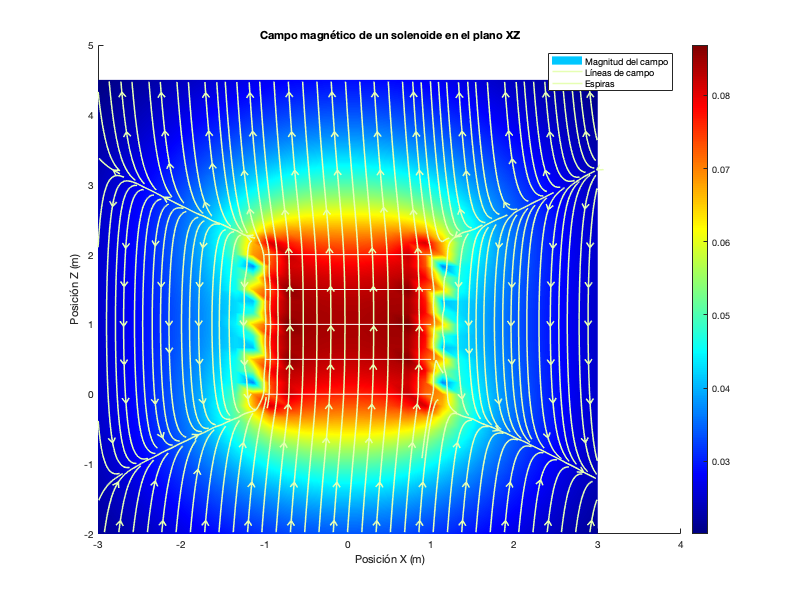


%% Visualización en el plano XZ (y=0)
centery = round(ny/2); % Seleccionamos el plano donde y ≈ 0, por simetría axial del solenoide

% Extraemos las componentes en el plano XZ
Bx_xz = squeeze(Bx(:,centery,:));
By_xz = squeeze(By(:,centery,:));
Bz_xz = squeeze(Bz(:,centery,:));
Bmag_xz = sqrt(Bx_xz.^2 + By_xz.^2 + Bz_xz.^2); % Magnitud del campo B

% Crear figura
figure(1);
set(gcf, 'Position', [100 100 800 600]);
hold on;

% Mapa de calor de la magnitud del campo
pcolor(x, z, (Bmag_xz').^(1/3)); % Se usa raíz cúbica para resaltar variaciones suaves
shading interp;
colormap(jet);
colorbar;
title('Magnitud del campo magnético (|B|^{1/3})');
xlabel('Posición X (m)');
ylabel('Posición Z (m)');

% Líneas de campo magnético
h = streamslice(x, z, Bx_xz', Bz_xz', 3); % Visualiza la dirección del campo
set(h, 'Color', [0.9 1 0.7], 'LineWidth', 1.5);

% Dibujar las espiras como referencia
for k = 1:nL
    z_pos = (k-1)*sz;
    plot(R*cos(linspace(0,2*pi,100)), z_pos + 0*linspace(0,2*pi,100), 'w-', 'LineWidth', 1); % contorno de espira
    plot([-R R], [z_pos z_pos], 'w--'); % línea representativa en Z
end

% Añadir título y leyenda
title('Campo magnético de un solenoide en el plano XZ');
legend('Magnitud del campo', 'Líneas de campo', 'Espiras', 'Location', 'northeast');

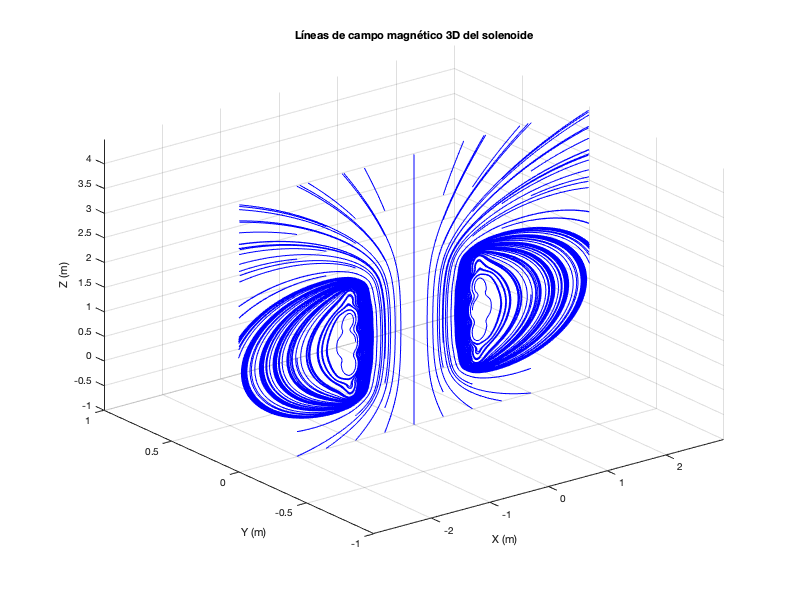


%% Visualización 3D de líneas de campo
figure(2);
set(gcf, 'Position', [100 100 800 600]);

% Seleccionar puntos de inicio para las líneas de campo
startx = -2:0.5:2; % Variación en X
starty = zeros(size(startx)); % Plano Y = 0 (simetría)
startz = -1:0.5:nL*sz+1; % Altura desde antes hasta después del solenoide

% Convertir a grid para streamline
[StartX, StartY, StartZ] = meshgrid(startx, starty, startz);

% Dibujar líneas de campo 3D
streamline(stream3(x, y, z, Bx, By, Bz, StartX, StartY, StartZ));
% Muestra cómo el campo magnético circula a través y alrededor del solenoide, en 3D

% Configuración de la figura
axis tight;
grid on;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Líneas de campo magnético 3D del solenoide');
view(3);
rotate3d on;


% Resumen físico:
% Este código simula el campo magnético generado por un solenoide compuesto por varias espiras circulares.
% Utiliza la Ley de Biot-Savart para calcular el campo B en el espacio alrededor del solenoide.
% El campo magnético es generado por elementos de corriente (dl) distribuidos a lo largo del alambre.
% Se visualiza tanto la magnitud del campo como sus líneas de flujo, mostrando cómo se concentra dentro del solenoide
% y se dispersa fuera de él, siguiendo el patrón característico de un dipolo magnético.
